`Erfan Panahi   810198369`

## `Wireless Cimmunication`

# `Computer Assignement #2`

# `Part 1. Narrow Band Channel`

clc
clear
close all

### `Problem 1. using BPSK modulation`

`Part a.`

- `Using theorical solution:` 

SNR_dB = -20:20;
SNR = 10.^(SNR_dB/10);
dhr = 0.001;
hr = -10:dhr:10;
BER_theorical_p1 = sum((1/sqrt(pi) * qfunc(sqrt(2*SNR).'*hr) .* exp(-hr.^2)).' * dhr);

- `Using simulation:`

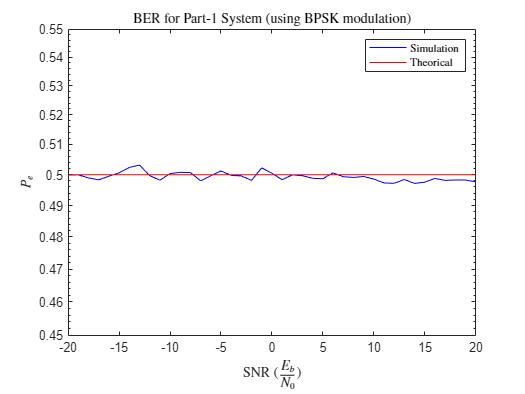

N = 1e5;
a = 1;
X = [-a, a];
x_ind = randi(2,[1,N]) - 1;
x = X(x_ind+1);
h = sqrt(1/2) * (randn(1,N) + randn(1,N)*1i);
BER_sim_p1 = [];
for N0 = a^2 ./ SNR
    w = sqrt(N0/2) * (randn(1,N) + randn(1,N)*1i);
    y = x.*h + w;
    x_hat = real(y) > 0;
    BER_sim_p1 = [BER_sim_p1 sum(x_ind ~= x_hat)/N];
end
figure
semilogy(SNR_dB, BER_sim_p1, 'b', SNR_dB, BER_theorical_p1, 'r')
legend('Simulation','Theorical','Interpreter','latex')
title('BER for Part-1 System (using BPSK modulation)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')
ylim([0.45 0.55]);

`Part b.`

- `Using theorical solution:` 

hr = 1;
% BER_theorical_p1_2 = 1/sqrt(pi) * qfunc(sqrt(2*SNR).'*hr) .* exp(-hr.^2);
BER_theorical_p1_2 = qfunc(sqrt(2*SNR));

- `Using simulation:`

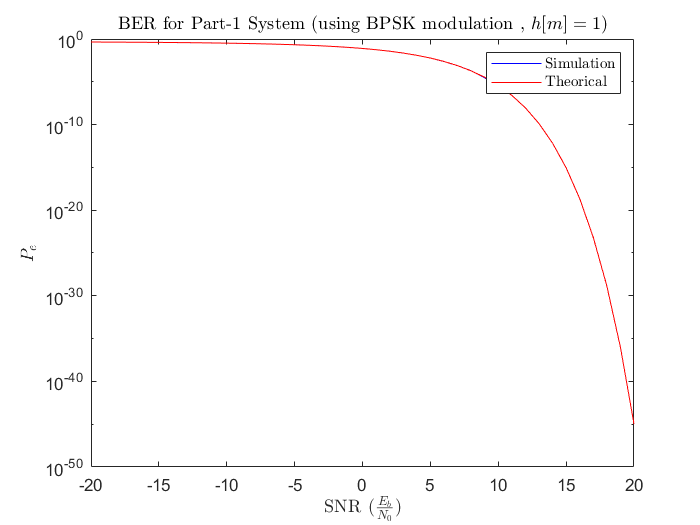

N = 1e6;
a = 1;
X = [-a, a];
x_ind = randi(2,[1,N]) - 1;
x = X(x_ind+1);
BER_sim_p1_2 = [];
for N0 = a^2 ./ SNR
    w = sqrt(N0/2) * (randn(1,N) + randn(1,N)*1i);
    y = x + w;
    x_hat = real(y) > 0;
    BER_sim_p1_2 = [BER_sim_p1_2 sum(x_ind ~= x_hat)/N];
end
figure
semilogy(SNR_dB, BER_sim_p1_2, 'b', SNR_dB, BER_theorical_p1_2, 'r')
legend('Simulation','Theorical','Interpreter','latex')
title('BER for Part-1 System (using BPSK modulation , $h[m]=1$)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

`Part c.`

snr = qfuncinv(1e-6)^2/2

snr = 11.2975

snr_dB = 10*log10(snr)

snr_dB = 10.5298

### `Problem 2. using Pulse Position modulation`

`Part a. ``Using theorical solution`

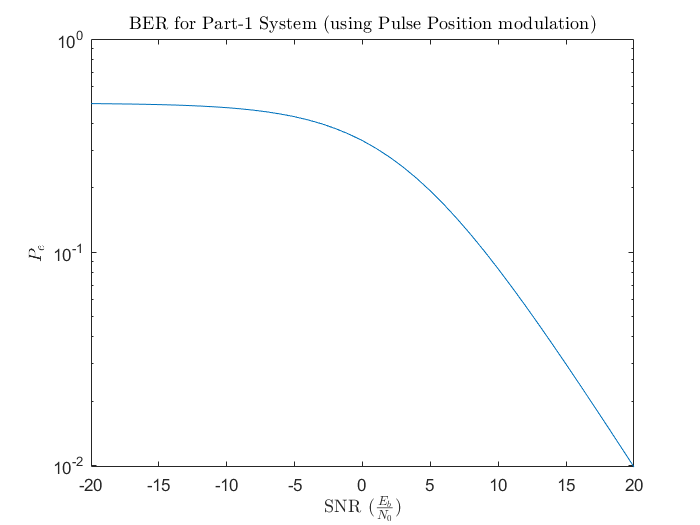

BER_theorical_p2 = 1./(2+SNR);
figure
semilogy(SNR_dB, BER_theorical_p2)
title('BER for Part-1 System (using Pulse Position modulation)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

`Part b.`` Using simulation `

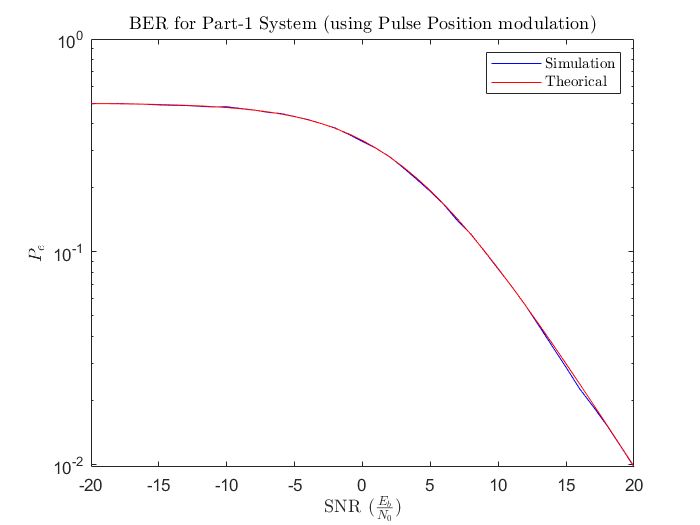

N = 1e5;
alpha = 1;
x = randi(2, [1,N]) - 1;
Y = [alpha, 0; 0, alpha];
yt = Y(x+1,:);
h = sqrt(1/2) * (randn(N, size(Y,2)) + randn(N, size(Y,2))*1i);
BER_sim_p2 = [];
for N0 = alpha^2 ./ SNR
    w = sqrt(N0/2) * (randn(N, size(Y,2)) + randn(N, size(Y,2))*1i);
    yr = yt.*h + w;
    x_hat = abs(yr(:,1)).^2 < abs(yr(:,2)).^2;
    BER_sim_p2 = [BER_sim_p2 sum(x.' ~= x_hat)/N];
end
figure
semilogy(SNR_dB, BER_sim_p2, 'b', SNR_dB, BER_theorical_p2, 'r')
legend('Simulation','Theorical','Interpreter','latex')
title('BER for Part-1 System (using Pulse Position modulation)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

`Part c.`

snr = (1-2e-6)/1e-6

snr = 1.0000e+06

snr_dB = 10*log10(snr)

snr_dB = 60.0000

### `Problem 3. using BPSK (CSI available in receiver)`

`Part a. ``Using theorical solution`

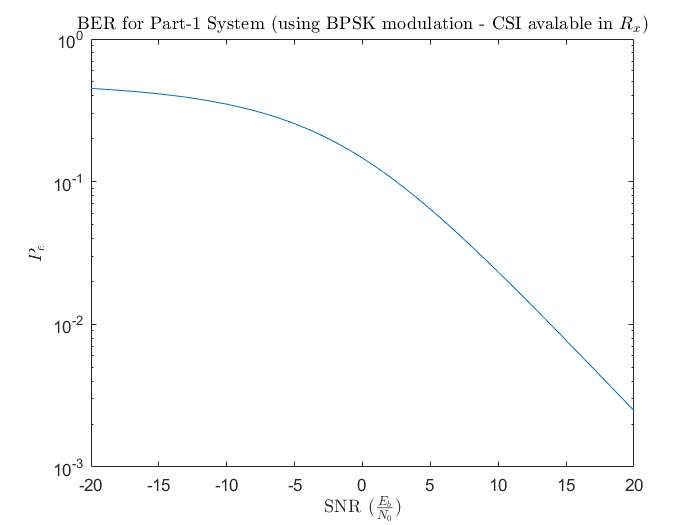

dhr = 0.01;
dhi = 0.01;
hr = -10:dhr:10;
hi = -10:dhi:10;
BER_theorical_p3 = 1/2 * (1 - sqrt(SNR ./ (1+SNR)));
figure
semilogy(SNR_dB, BER_theorical_p3)
title('BER for Part-1 System (using BPSK modulation - CSI avalable in $R_x$)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

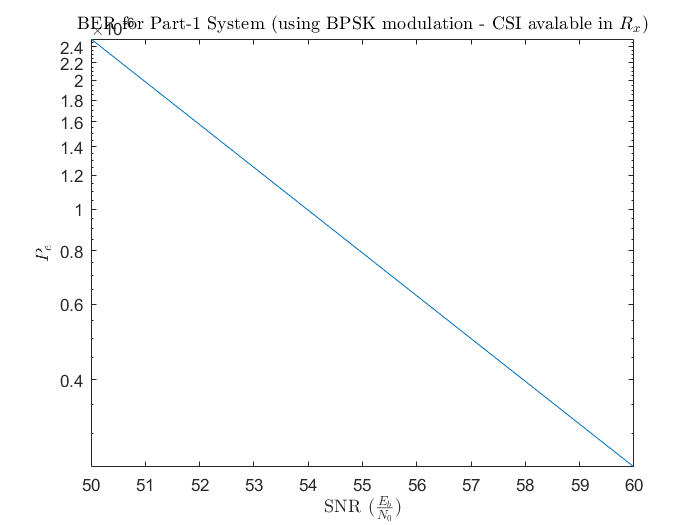

dhr = 0.001;
dhi = 0.001;
hr = -10:dhr:10;
hi = -10:dhi:10;
SNR1_dB = 50:60;
SNR1 = 10.^(SNR1_dB/10);
BER_theorical = 1/2 * (1 - sqrt(SNR1 ./ (1+SNR1)));
figure
semilogy(SNR1_dB, BER_theorical)
title('BER for Part-1 System (using BPSK modulation - CSI avalable in $R_x$)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

`Part b.`` Using simulation `

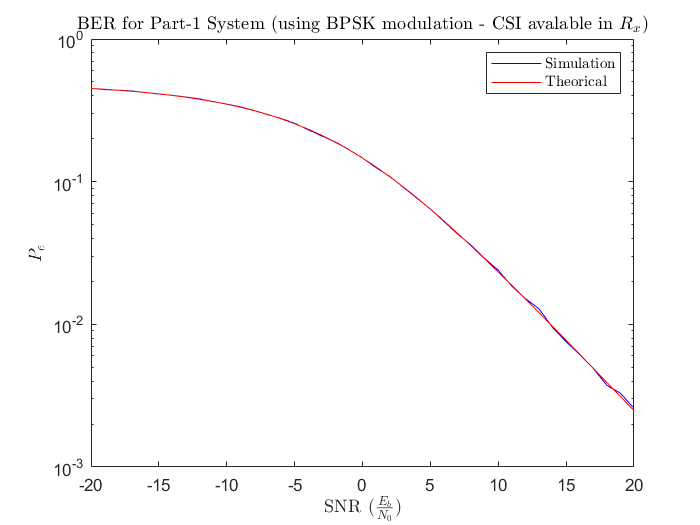

N = 1e5;
a = 1;
X = [-a, a];
x_ind = randi(2,[1,N]) - 1;
x = X(x_ind+1);
h = sqrt(1/2) * (randn(1,N) + randn(1,N)*1i);
BER_sim_p3 = [];
for N0 = a^2 ./ SNR
    w = sqrt(N0/2) * (randn(1,N) + randn(1,N)*1i);
    y = x.*h + w;
    z = y .* conj(h) ./ abs(h).^2;
    x_hat = real(z) > 0;
    BER_sim_p3 = [BER_sim_p3 sum(x_ind ~= x_hat)/N];
end
figure
semilogy(SNR_dB, BER_sim_p3, 'b', SNR_dB, BER_theorical_p3, 'r')
legend('Simulation','Theorical','Interpreter','latex')
title('BER for Part-1 System (using BPSK modulation - CSI avalable in $R_x$)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

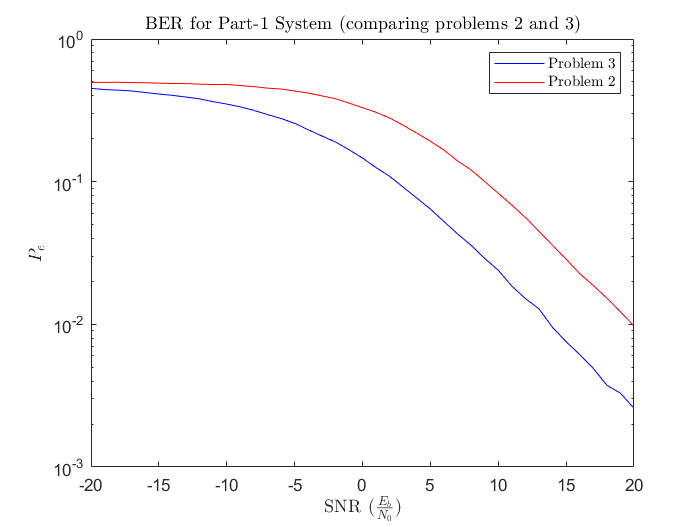

figure
semilogy(SNR_dB, BER_sim_p3, 'b', SNR_dB, BER_sim_p2, 'r')
legend('Problem 3','Problem 2','Interpreter','latex')
title('BER for Part-1 System (comparing problems 2 and 3)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

ratio = BER_sim_p2(end) / BER_sim_p3(end);
ratio_dB = 10*log10(ratio)

ratio_dB = 5.7694

### `Problem 4. using QPSK (CSI available in receiver)`

`Part a. `

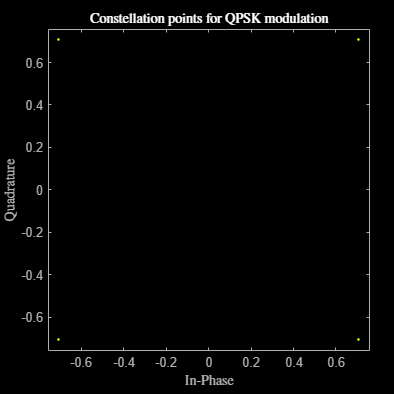

a = 1;
cons = a/sqrt(2)*[1+1i, -1+1i, 1-1i, -1-1i];
scatterplot(cons)
title('Constellation points for QPSK modulation','Interpreter','latex')
xlabel('In-Phase','Interpreter','latex')
ylabel('Quadrature','Interpreter','latex')

- `Using theorical solution:`

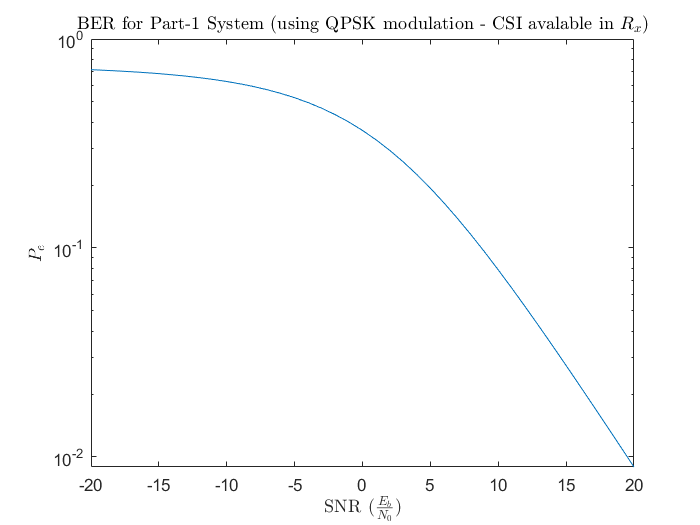

dhr = 0.01;
dhi = 0.01;
hr = -10:dhr:10;
hi = -10:dhi:10;
BER_theorical_p4 = zeros(1,length(SNR));
for i = 1:length(SNR)
    BER_theorical_p4(i) = 1 - 1/pi * sum(sum((1-qfunc(sqrt(SNR(i)*(hr.^2 + hi.^2.')))).^2 .* exp(-hr.^2 - hi.^2.') * dhr * dhi));
end
figure
semilogy(SNR_dB, BER_theorical_p4)
title('BER for Part-1 System (using QPSK modulation - CSI avalable in $R_x$)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

- `Using simulation:`

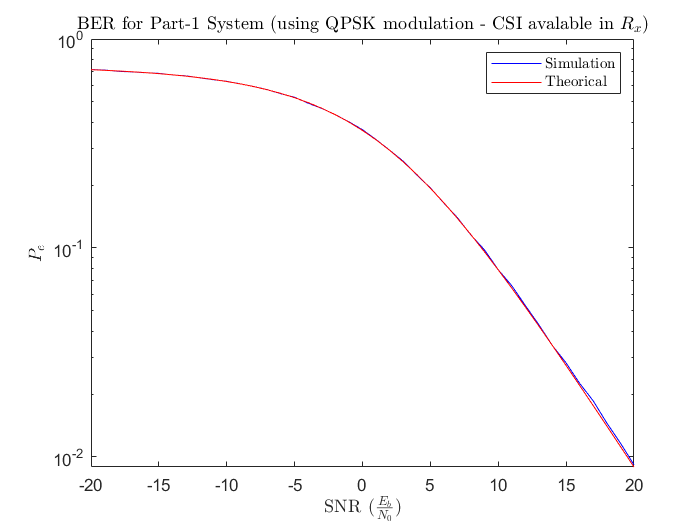

N = 1e5;
a = 1;
x_ind = randi(4,[1,N]) - 1;
x = cons(x_ind+1);
h = sqrt(1/2) * (randn(1,N) + randn(1,N)*1i);
BER_sim_p4 = [];
for N0 = a^2 ./ SNR
    w = sqrt(N0/2) * (randn(1,N) + randn(1,N)*1i);
    y = x.*h + w;
    z = y .* conj(h) ./ abs(h).^2;
    x_hat = 2 * (imag(z) < 0) + (real(z) < 0);
    BER_sim_p4 = [BER_sim_p4 sum(x_ind ~= x_hat)/N];
end
figure
semilogy(SNR_dB, BER_sim_p4, 'b', SNR_dB, BER_theorical_p4, 'r')
legend('Simulation','Theorical','Interpreter','latex')
title('BER for Part-1 System (using QPSK modulation - CSI avalable in $R_x$)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

`Part a. ``Comparing Problem 2 and 4`

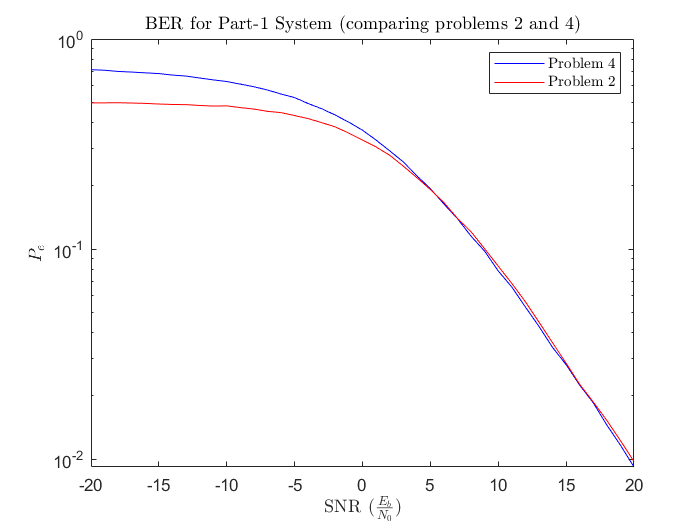

figure
semilogy(SNR_dB, BER_sim_p4, 'b', SNR_dB, BER_sim_p2, 'r')
legend('Problem 4','Problem 2','Interpreter','latex')
title('BER for Part-1 System (comparing problems 2 and 4)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

ratio = BER_sim_p2(end) / BER_sim_p4(end);
ratio_dB = 10*log10(ratio)

ratio_dB = 0.2619

### `Problem 5. using Time-Diversity `

- `Using theorical solution:`

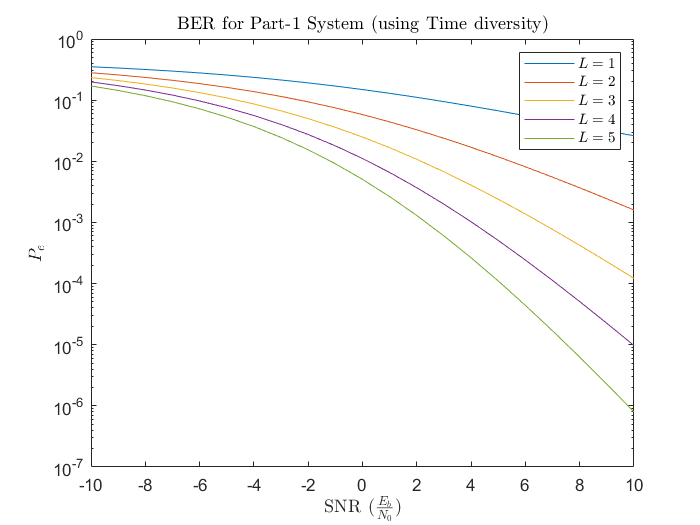

SNR_dB = -10:10;
SNR = 10.^(SNR_dB/10);
dh = 0.01;
h = 0:dh:100;
Pe_therical_p5 = @(L) 1/factorial(L-1) .* sum((qfunc(sqrt(2*SNR.'*h)) .* h.^(L-1) .* exp(-h)).' * dh);
L = 5;
BER_theorical_p5 = zeros(L,length(SNR));
for l = 1:L
    BER_theorical_p5(l,:) = Pe_therical_p5(l);
end
figure
semilogy(SNR_dB, BER_theorical_p5)
legend('$L=1$','$L=2$','$L=3$','$L=4$','$L=5$','Interpreter','latex')
title('BER for Part-1 System (using Time diversity)','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

- `Using simulation:`

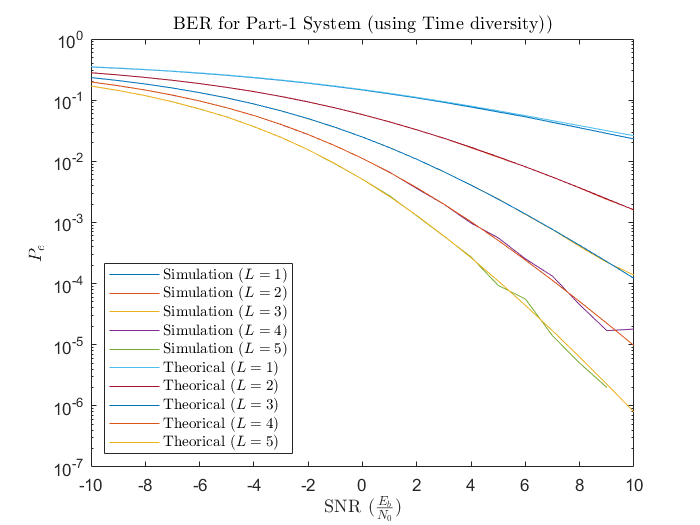

N = 1e6;
BER_sim_p5 = zeros(L,length(SNR));
for l = 1:L
    BER_sim_p5(l,:) = P5_sim(l, N, SNR);
end
figure
semilogy(SNR_dB, [BER_sim_p5; BER_theorical_p5])
legend('Simulation ($L=1$)','Simulation ($L=2$)','Simulation ($L=3$)','Simulation ($L=4$)','Simulation ($L=5$)','Theorical ($L=1$)','Theorical ($L=2$)','Theorical ($L=3$)','Theorical ($L=4$)','Theorical ($L=5$)','Interpreter','latex', 'Location','SouthWest')
title('BER for Part-1 System (using Time diversity))','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

### `Problem 6. using Space-Diversity `

- `Using simulation:`

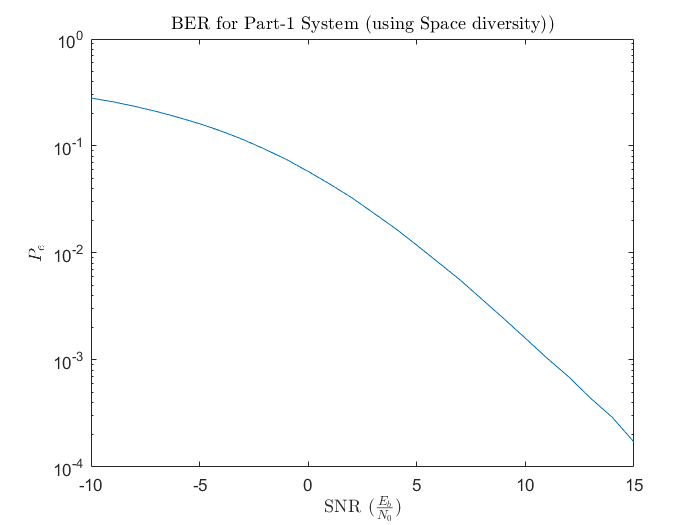

SNR_dB = -10:15;
SNR = 10.^(SNR_dB/10);
N = 1e6;
a = 1;
X = [-a, a];
x_ind = randi(2,[1,N]) - 1;
x = X(x_ind+1);
h = sqrt(1/2) * (randn(2,N/2) + randn(2,N/2)*1i);
x_ts1 = reshape(x,[2,N/2]);
x_ts2 = [-conj(x_ts1(2,:)); conj(x_ts1(1,:))];
BER_sim_p6 = [];
z = zeros(1, N);
for N0 = a^2 ./ SNR
    w = sqrt(N0/2) * (randn(2,N/2) + randn(2,N/2)*1i);
    y_t1 = sum(h .* x_ts1,1) + w(1,:); 
    y_t2 = sum(h .* x_ts2,1) + w(2,:);
    m1 = conj(h(1,:)) .* y_t1 + h(2,:) .* conj(y_t2);
    m2 = conj(h(2,:)) .* y_t1 - h(1,:) .* conj(y_t2);
    z(1:2:N) = m1; 
    z(2:2:N) = m2;
    x_hat = real(z) > 0;
    BER_sim_p6 = [BER_sim_p6 sum(x_ind ~= x_hat)/N];
end
figure
semilogy(SNR_dB, BER_sim_p6)
title('BER for Part-1 System (using Space diversity))','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

- `Comparing spade-diversity and time-diversity with `$L=2$`:`

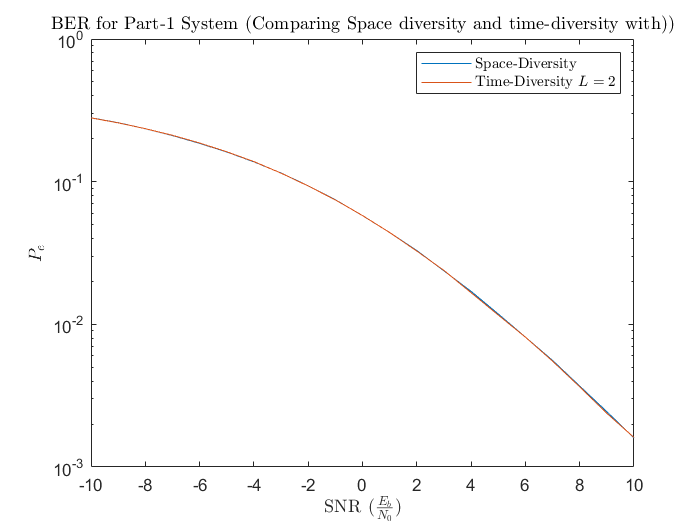

SNR_dB = -10:10;
figure
semilogy(SNR_dB, [BER_sim_p6(1:length(SNR_dB)); BER_sim_p5(2,:)])
title('BER for Part-1 System (Comparing Space diversity and time-diversity with))','Interpreter','latex')
legend('Space-Diversity','Time-Diversity $L=2$','Interpreter','latex')
xlabel('SNR ($\frac{E_b}{N_0}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

# `Part 2. Wide-Band Channel`

clc
clear
warning off

`Definitions:`

nc = 1e4;
L = 200;
N = 2e6;
Number_of_Blocks = N / nc;
SNR_dB = -20:20;
alpha = 1;
X = [-alpha, alpha];
a_ind = randi(2,[1,N]) - 1;
A = X(a_ind+1);

### `Problem 5. Channel capacity and BER for the designed OFDM system`

- `Using fzero:`

BER_p5 = [];
Capacity = []; 
for snr = SNR_dB
    Pmax = nc;
    SNR = 10^(snr/10);
    N0 = Pmax / (nc * SNR);
    ber = 0; 
    capacity = 0;
    for num_block = 1:Number_of_Blocks-1
        % Defining new OFDM block
        a_ind_t = a_ind(num_block*nc+1:(num_block+1)*nc);
        At = A(num_block*nc+1:(num_block+1)*nc);
        % New channel coeffients
        h = sqrt(1/2) * (randn(1,L) + randn(1,L)*1i);
        H = fft(h ,nc);
        % Solving optimization problem to achieve waterfilling coeffients
        C = @(lambda) sum(log2(1+ max(abs(H).^2/(lambda*N0) - 1, 0)));
        f = @(lambda) Pmax - sum(max(1/lambda - N0./abs(H).^2,0));
        Lambda = fzero(f,1);
        capacity = capacity + C(Lambda); 
        P = max(1/Lambda - N0./abs(H).^2, 0);
        % Transmitter 
        At_w = At .* sqrt(P) .* exp(-1i*angle(H));
        a = ifft(At_w, nc);
        cp = a(end-L+1:end);
        a_ = [cp, a];
        % Receiver
        w = sqrt(N0/2) * (randn(1,nc+L) + randn(1,nc+L)*1i);
        y_ = conv(a_, h);
        y_ = y_(1:end-L+1) + w;
        y = y_(L+1:end);
        Y = fft(y, nc);
        % Detection
        Z = real(Y) > 0;
        ber = ber + sum(a_ind_t ~= Z); 
    end
    BER_p5 = [BER_p5 ber/(nc*(num_block+1))];
    Capacity = [Capacity capacity/num_block];
end
figure
semilogy(SNR_dB, BER_p5)
title('BER for Part-2 System (Waterfilling)','Interpreter','latex')
xlabel('SNR ($\frac{P_max}{N_0n_c}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')
semilogy(SNR_dB, Capacity)
title('Channel Capacity for Part-2 System (Waterfilling)','Interpreter','latex')
xlabel('SNR ($\frac{P_max}{N_0n_c}$)','Interpreter','latex')
ylabel('$Capacity$','Interpreter','latex')

- `Using fmincon:`

BER_p5 = [];
Capacity = [];
global Pmax H N0; 
for snr = SNR_dB
    Pmax = nc;
    SNR = 10^(snr/10);
    N0 = Pmax / (nc * SNR);
    ber = 0; 
    capacity = 0;
    for num_block = 1:Number_of_Blocks-1
        % Defining new OFDM block
        a_ind_t = a_ind(num_block*nc+1:(num_block+1)*nc);
        At = A(num_block*nc+1:(num_block+1)*nc);
        % New channel coeffients
        h = sqrt(1/2) * (randn(1,L) + randn(1,L)*1i);
        H = fft(h ,nc);
        % Solving optimization problem to achieve waterfilling coeffients
        C = @(lambda) -sum(log2(1+ max(abs(H).^2/(lambda*N0) - 1, 0)));
        x0 = 0.1;
        Lambda = fmincon(C,x0,[],[],[],[],[],[],@Const);
        capacity = capacity - C(Lambda); 
        P = max(1/Lambda - N0./abs(H).^2, 0);
        % Transmitter 
        At_w = At .* sqrt(P) .* exp(-1i*angle(H));
        a = ifft(At_w, nc);
        cp = a(end-L+1:end);
        a_ = [cp, a];
        % Receiver
        w = sqrt(N0/2) * (randn(1,nc+L) + randn(1,nc+L)*1i);
        y_ = conv(a_, h);
        y_ = y_(1:end-L+1) + w;
        y = y_(L+1:end);
        Y = fft(y, nc);
        % Detection
        Z = real(Y) > 0;
        ber = ber + sum(a_ind_t ~= Z); 
    end
    BER_p5 = [BER_p5 ber/(nc*(num_block+1))];
    Capacity = [Capacity capacity/num_block];
end
figure
semilogy(SNR_dB, BER_p5)
title('BER for Part-2 System (Waterfilling)','Interpreter','latex')
xlabel('SNR ($\frac{P_max}{N_0n_c}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')
figure
semilogy(SNR_dB, Capacity)
title('Channel Capacity for Part-2 System (Waterfilling)','Interpreter','latex')
xlabel('SNR ($\frac{P_max}{N_0n_c}$)','Interpreter','latex')
ylabel('$Capacity$','Interpreter','latex')

`Problem 6. Diversity in Receiver`

BER_p6 = [];
k = 10;
for snr = SNR_dB
    SNR = 10^(snr/10);
    Pmax = sum(A.^2);
    N0 = Pmax / (N * SNR);
    ber = 0;
    for num_block = 0:Number_of_Blocks-1
        % Defining new OFDM block
        a_ind_t = a_ind(num_block*nc+1:(num_block+1)*nc);
        At = A(num_block*nc+1:(num_block+1)*nc);
        % New channel coeffients
        h = sqrt(1/2) * (randn(k,L) + randn(k,L)*1i);
        % Transmitter
        a = ifft(At, nc);
        cp = a(end-L+1:end);
        a_ = [cp, a];
        % Receiver
        Y = 0;
        for i = 1:k
            H = fft(h(i,:), nc);
            y_ = conv(a_, h(i,:));
            w = sqrt(N0/2) * (randn(1,nc+L) + randn(1,nc+L)*1i);
            y_ = y_(:,1:end-L+1) + w;
            y = y_(L+1:end);
            Y_in = fft(y, nc);
            Theta = angle(H);
            r = sqrt(abs(H).^2 / (N0*nc));
            alpha = r .* exp(-1i*Theta);
            Y_out = Y_in .* alpha;
            Y = Y + Y_out;
        end
        % Detection
        Z = real(Y) > 0;
        ber = ber + sum(a_ind_t ~= Z); 
    end
    BER_p6 = [BER_p6 ber/N];
end
figure
semilogy(SNR_dB, BER_p6)
title('BER for Part-2 System (Diversity in Receiver - MRC)','Interpreter','latex')
xlabel('SNR ($\frac{P_max}{N_0n_c}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

`Problem 7. Equalization`

BER_p7_ZF = [];
BER_p7_MMSE = [];
for snr = -20:40
    SNR = 10^(snr/10);
    Pmax = sum(A.^2);
    N0 = Pmax / (N * SNR);
    ber_zf = 0;
    ber_mmse = 0;
    for num_block = 0:Number_of_Blocks-1
        % Defining new OFDM block
        a_ind_t = a_ind(num_block*nc+1:(num_block+1)*nc);
        At = A(num_block*nc+1:(num_block+1)*nc);
        % New channel coeffients
        h = sqrt(1/2) * (randn(1,L) + randn(1,L)*1i);
        H = fft([h zeros(1,nc-length(h))], nc);
        % Transmitter
        a = ifft(At, nc);                   
        cp = a(end-L+1:end);
        a_ = [cp, a];
        % Receiver
        w = sqrt(N0/2) * (randn(1,nc+L) + randn(1,nc+L)*1i);
        y_ = conv(a_, h);
        y_ = y_(1:end-L+1) + w;
        y = y_(L+1:end);
        Y = fft(y, nc);
        % Detection
        Z_zf = real(Y ./ H) > 0;
        Z_mmse = real(Y .* conj(H) ./ (abs(H).^2 + N0./(nc * alpha.^2))) > 0;
        ber_zf = ber_zf + sum(a_ind_t ~= Z_zf); 
        ber_mmse = ber_mmse + sum(a_ind_t ~= Z_mmse); 
    end
    BER_p7_ZF = [BER_p7_ZF ber_zf/((num_block+1)*nc)];
    BER_p7_MMSE = [BER_p7_MMSE ber_mmse/N];
end
figure
semilogy(-20:40, [BER_p7_ZF; BER_p7_MMSE])
title('BER for Part-2 System (using equalizer)','Interpreter','latex')
legend('ZF','MMSE','Interpreter','latex')
xlabel('SNR ($\frac{P_max}{N_0n_c}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

`Problem 8. Effect of clipping in receiver`

BER_p8 = [];
for snr = -20:40
    SNR = 10^(snr/10);
    Pmax = sum(A.^2);
    N0 = Pmax / (N * SNR);
    ber_mmse = 0;
    for num_block = 0:Number_of_Blocks-1
        % Defining new OFDM block
        a_ind_t = a_ind(num_block*nc+1:(num_block+1)*nc);
        At = A(num_block*nc+1:(num_block+1)*nc);
        % New channel coeffients
        h = sqrt(1/2) * (randn(1,L) + randn(1,L)*1i);
        H = fft([h zeros(1,nc-length(h))], nc);
        % Transmitter
        a = ifft(At, nc);
        ind = abs(a) > 0.5*max(abs(a));
        a(ind) = 0.5*max(abs(a)) .* exp(1i*angle(a(ind)));
        cp = a(end-L+1:end);
        a_ = [cp, a];
        % Receiver
        w = sqrt(N0/2) * (randn(1,nc+L) + randn(1,nc+L)*1i);
        y_ = conv(a_, h);
        y_ = y_(1:end-L+1) + w;
        y = y_(L+1:end);
        Y = fft(y, nc);
        % Detection
        Z_mmse = real(Y .* conj(H) ./ (abs(H).^2 + N0./(nc * alpha.^2))) > 0;
        ber_mmse = ber_mmse + sum(a_ind_t ~= Z_mmse); 
    end
    BER_p8 = [BER_p8 ber_mmse/N];
end
figure
semilogy(-20:40, [BER_p8; BER_p7_MMSE])
title('BER for Part-2 System (Clipping)','Interpreter','latex')
legend('with Clipping','without Clipping','Interpreter','latex')
xlabel('SNR ($\frac{P_max}{N_0n_c}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

`Comparing Parts 5 to 8.`

figure
semilogy(SNR_dB, [BER_p5; BER_p6; BER_p7_ZF(1:41); BER_p7_MMSE(1:41); BER_p8(1:41)])
title('BER for Part-2 System (Comparing)','Interpreter','latex')
legend('Waterfilling','Diversity','ZF eqz.','MMSE eqz.','Clipping','Interpreter','latex')
xlabel('SNR ($\frac{P_max}{N_0n_c}$)','Interpreter','latex')
ylabel('$P_e$','Interpreter','latex')

function BER_sim = P5_sim(L, N, SNR)
    a = 1;
    X = [-a, a];
    x_ind = randi(2,[1,N]) - 1;
    x = X(x_ind+1);
    h = sqrt(1/2) * (randn(L,N) + randn(L,N)*1i);
    BER_sim = [];
    for N0 = a^2 ./ SNR
        w = sqrt(N0/2) * (randn(L,N) + randn(L,N)*1i);
        y = x.*h + w;
        Theta = angle(h);
        r = sqrt(abs(h).^2 / N0);
        alpha = r .* exp(-1i*Theta);
        z = sum(y .* alpha, 1);
        x_hat = real(z) > 0;
        BER_sim = [BER_sim sum(x_ind ~= x_hat)/N];
    end
end

function [c1, c2] = Const(lambda)
    global Pmax H N0; 
    c1 = [];
    c2 = sum(max(1/lambda - N0./abs(H).^2, 0)) - Pmax;
end